clearvars;
format shortG
xmin = -10;
xmax = 10;
ymin = 0;
ymax = 0;
zmin = 0;
zmax = 0;
xint = 0.5;
yint = 0;
zint = 0;
xtotal = ((xmax-xmin)/xint + 1);
ytotal = ((ymax-ymin)/yint + 1);
ztotal = ((zmax-zmin)/zint + 1);
datasize = xtotal*ytotal*ztotal;

diameter = 3/16*25.4; %mm
height = 1/8*25.4; %mm
Br_max = 12100*0.1; %mT
mu_0 =  4*pi*10^-7*1000*1000; % mT mm/A^2

%want M in A/m
M=Br_max;
B_t = pi*(diameter/2)^2*height*Br_max/(4*pi);

location = [];
z = zmin;
dataavg = [];

for k = 1:ztotal
    zstr = sprintf('%.1f', z);
    y = ymin;

    for j = 1:ytotal
        ystr = sprintf('%.1f', y);
        x = xmin;

        for i = 1:xtotal

            xstr = sprintf('%.1f', x);
            filename = append('C:\Users\nguye\OneDrive\Watanabe_Project\PIM05242023_calibration\xcheck\',xstr,'_',ystr,'_',zstr,'.data');
            test = importdata(filename);
            
            bx1 = test.data(1:99,6);
            by1 = test.data(1:99,7);
            bz1 = test.data(1:99,8);

            bx2 = test.data(100:199,6);
            by2 = test.data(100:199,7);
            bz2 = test.data(100:199,8);

            bx3 = test.data(200:299,6);
            by3 = test.data(200:299,7);
            bz3 = test.data(200:299,8);
            
            bx4 = test.data(300:399,6);
            by4 = test.data(300:399,7);
            bz4 = test.data(300:399,8);
            dataavg = [dataavg 
                [mean(bx1) mean(by1) mean(bz1) mean(bx2) mean(by2) mean(bz2) mean(bx3) mean(by3) mean(bz3) mean(bx4) mean(by4) mean(bz4)]];
            location = [location; x y z];
           
            x = x + xint;
        end
        y = y + yint;
    end
    z = z + zint;
end

location

location =           -10            0            0
         -9.5            0            0
           -9            0            0
         -8.5            0            0
           -8            0            0
         -7.5            0            0
           -7            0            0
         -6.5            0            0
           -6            0            0
         -5.5            0            0


dataavg

dataavg =     -0.028813     0.034281    -0.014077    -0.012219     0.024982   -0.0076334    -0.047666    0.0056793      0.11315    -0.035447     0.012978    -0.011843
    -0.028699     0.034357    -0.014109     -0.01228     0.025167   -0.0078103    -0.047256    0.0057007      0.11364    -0.035603     0.012998    -0.011747
     -0.02851     0.034435    -0.014078    -0.012331     0.025258   -0.0076208    -0.046437    0.0057191      0.11447    -0.035829     0.012973    -0.011579
    -0.028224     0.034561    -0.014036    -0.012355     0.025273   -0.0075436    -0.045484     0.005811      0.11572    -0.036116     0.012987    -0.011348
     -0.02785      0.03474    -0.013942    -0.012462     0.025435   -0.0075726    -0.044191    0.0058817      0.11708    -0.036524     0.013066    -0.011094
    -0.027492     0.034885    -0.013895    -0.012538     0.025599   -0.0074541    -0.042736    0.0060261      0.11855    -0.036963     0.013065    -0.010783
    -0.027095     0.035093    -0.013846    -0.01

sen1 = dataavg(:,1:3)

sen1 =     -0.028813     0.034281    -0.014077
    -0.028699     0.034357    -0.014109
     -0.02851     0.034435    -0.014078
    -0.028224     0.034561    -0.014036
     -0.02785      0.03474    -0.013942
    -0.027492     0.034885    -0.013895
    -0.027095     0.035093    -0.013846
    -0.026581     0.035311     -0.01372
    -0.025984     0.035609    -0.013607
     -0.02533     0.035844    -0.013499


sen2 = dataavg(:,4:6)

sen2 =     -0.012219     0.024982   -0.0076334
     -0.01228     0.025167   -0.0078103
    -0.012331     0.025258   -0.0076208
    -0.012355     0.025273   -0.0075436
    -0.012462     0.025435   -0.0075726
    -0.012538     0.025599   -0.0074541
    -0.012686     0.025827   -0.0075727
     -0.01276     0.026038   -0.0076036
    -0.012972     0.026389   -0.0073139
    -0.013138     0.026738     -0.00716


sen3 = dataavg(:,7:9)

sen3 =     -0.047666    0.0056793      0.11315
    -0.047256    0.0057007      0.11364
    -0.046437    0.0057191      0.11447
    -0.045484     0.005811      0.11572
    -0.044191    0.0058817      0.11708
    -0.042736    0.0060261      0.11855
    -0.040989    0.0060813      0.12024
    -0.038978    0.0061187      0.12184
    -0.036241    0.0061591      0.12392
    -0.033388    0.0060889      0.12593


sen4 = dataavg(:,10:12)

sen4 =     -0.035447     0.012978    -0.011843
    -0.035603     0.012998    -0.011747
    -0.035829     0.012973    -0.011579
    -0.036116     0.012987    -0.011348
    -0.036524     0.013066    -0.011094
    -0.036963     0.013065    -0.010783
    -0.037551     0.013063    -0.010407
     -0.03809     0.013036    -0.010012
    -0.038862     0.013022    -0.009391
    -0.039608     0.013012   -0.0088409


ind = 10;
d_data = sen1;
loc = location;
datasize = length(sen1)

datasize =     41


dcostfun = @(v)anglecost(v, loc, d_data, B_t, datasize);
nonlcon = @con;
        
x0 = [0,0,0];
A = [];
b = [];
Aeq = [];
beq = [];
lb = [-1,-1,-1];
ub = [1,1,1];
[min1, fval] = fmincon(dcostfun, x0, A, b, Aeq, beq, lb, ub, nonlcon)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


min1 =       0.19663     -0.98024    -0.021708


fval =        3.3674


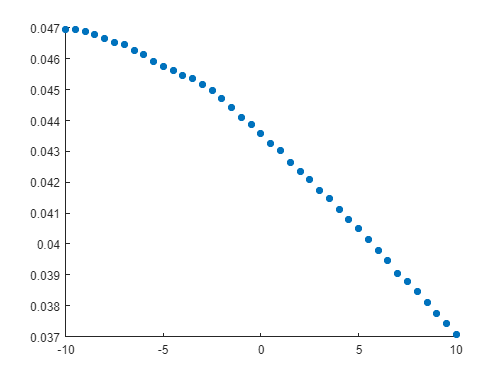

scatter(location(:,1), sqrt(sum(sen1.^2, 2)), 'filled') %bottom left

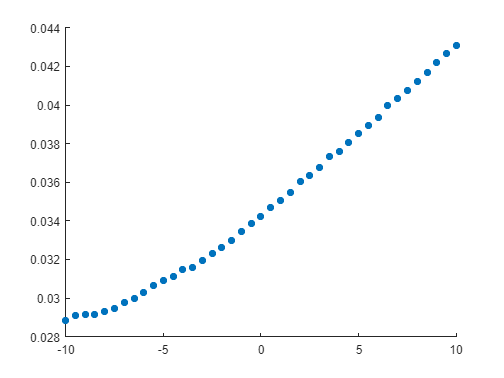

scatter(location(:,1), sqrt(sum(sen2.^2, 2)), 'filled') %bottom right

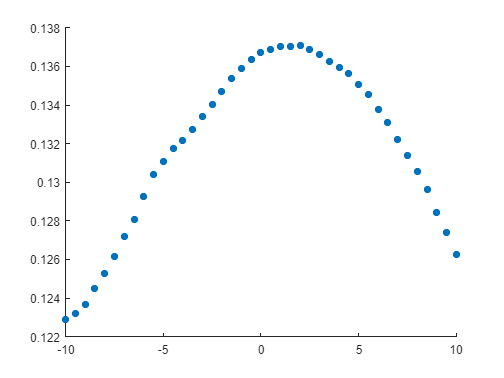

scatter(location(:,1), sqrt(sum(sen3.^2, 2)), 'filled') %top left (magnet centered on this one)

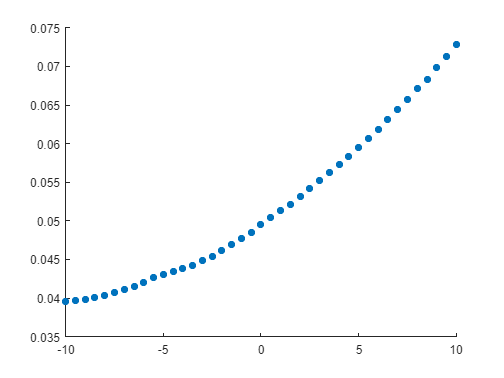

scatter(location(:,1), sqrt(sum(sen4.^2, 2)), 'filled') %top right

breaker = 10000

breaker =        10000


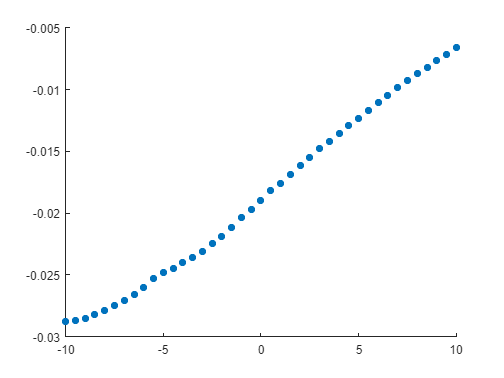

scatter(location(:,1), sen1(:,1), 'filled') %bottom left

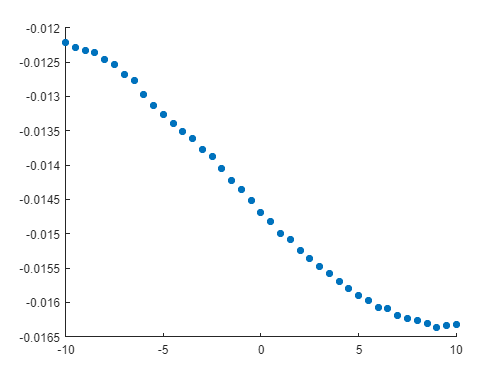

scatter(location(:,1), sen2(:,1), 'filled') %bottom right

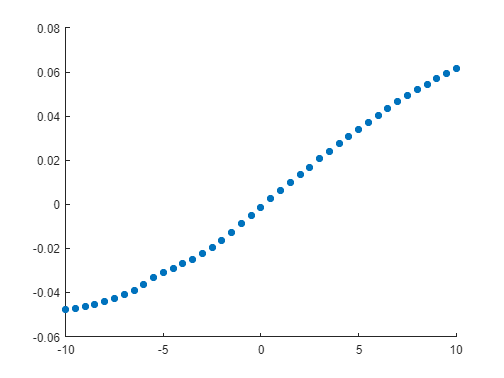

scatter(location(:,1), sen3(:,1), 'filled') %top left (magnet centered on this one)

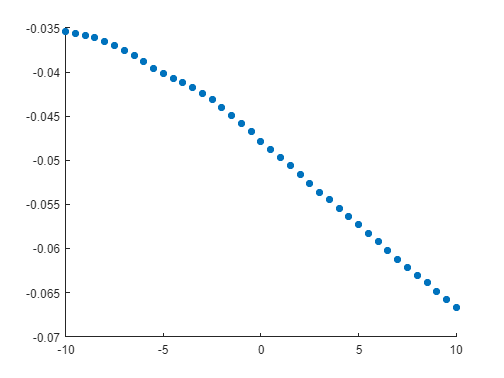

scatter(location(:,1), sen4(:,1), 'filled') %top right

breaker

breaker =        10000


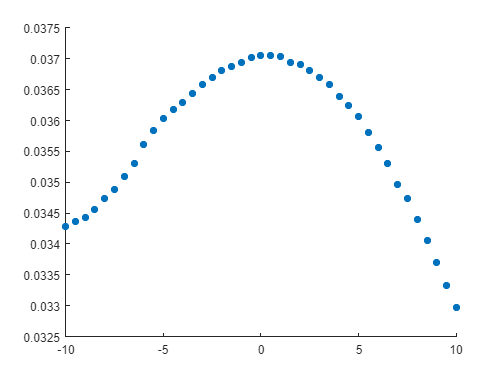

scatter(location(:,1), sen1(:,2), 'filled') %bottom left

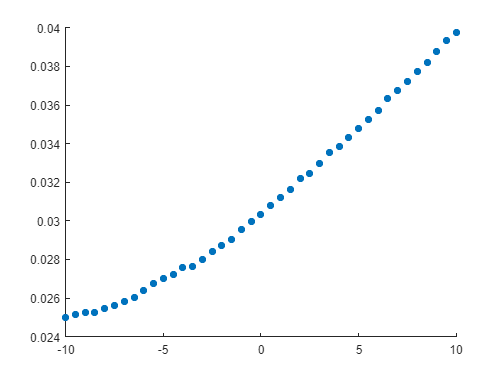

scatter(location(:,1), sen2(:,2), 'filled') %bottom right

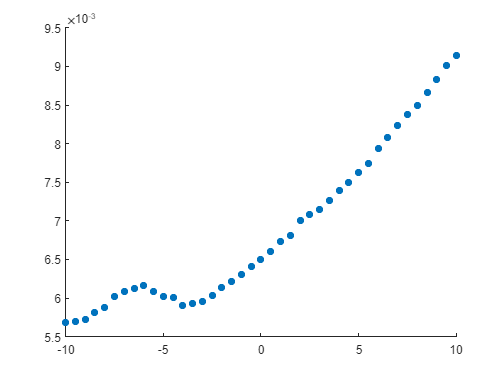

scatter(location(:,1), sen3(:,2), 'filled') %top left (magnet centered on this one)

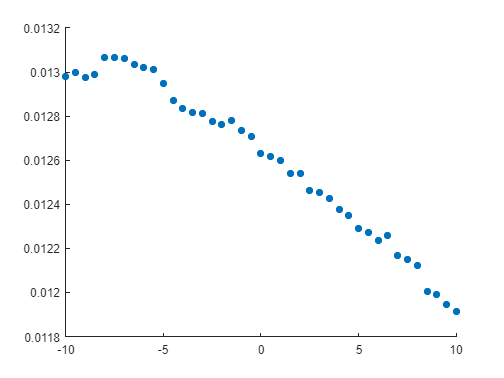

scatter(location(:,1), sen4(:,2), 'filled') %top right

breaker

breaker =        10000


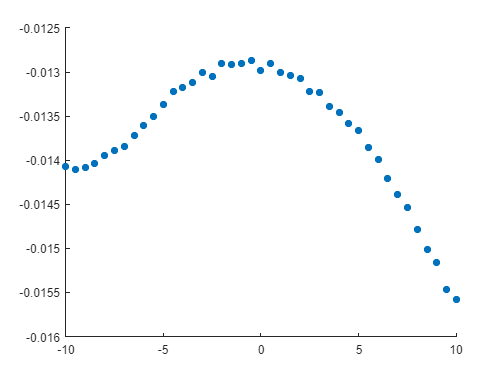

scatter(location(:,1), sen1(:,3), 'filled') %bottom left

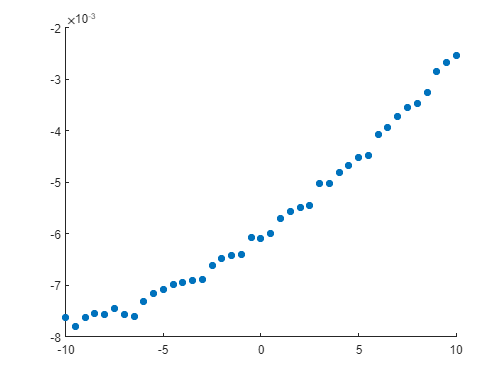

scatter(location(:,1), sen2(:,3), 'filled') %bottom right

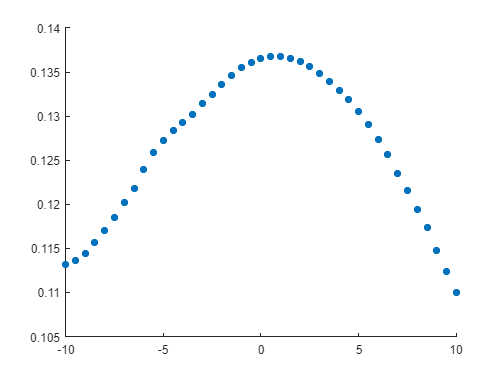

scatter(location(:,1), sen3(:,3), 'filled') %top left (magnet centered on this one)

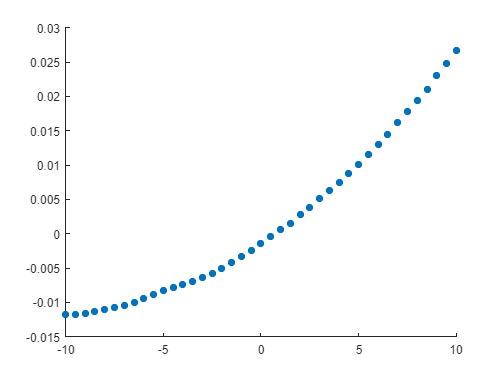

scatter(location(:,1), sen4(:,3), 'filled') %top right

breaker

breaker =        10000


function a = anglecost(v, loc, B_data, B_t, datasize)
X1 = [0 0 -25] - loc;
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem([v(1) v(2) v(3)], datasize, 1);
a = sum(sum((B_data - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2));
end

function [c, ceq] = con(v)
c = [];
ceq = sqrt(sum([v(1) v(2) v(3)].^2, 2)) - 1;
end